%%
% Detect words 
afile = 'C:\Users\gfraga\Downloads\s01_de-DE-Neural2-F.wav'

afile = 'C:\Users\gfraga\Downloads\s01_de-DE-Neural2-F.wav'

fs = 24e3;
[speech,fileFs] = audioread(afile);
speech = resample(speech,fs,fileFs);
speech = speech/max(abs(speech));
%sound(speech,fs)

%
close all 

winresizer = 36;
win = hamming(winresizer*1e-3*fs,"periodic");

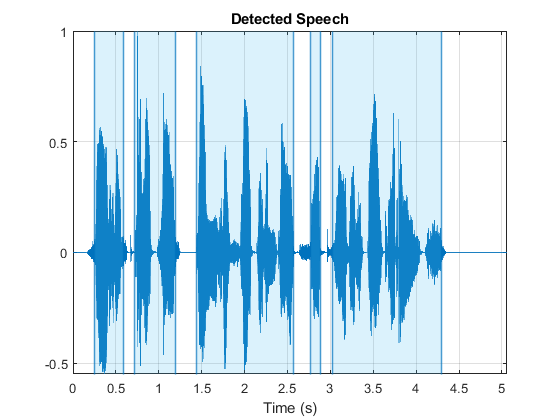

detectSpeech(speech,fs,Window=win)